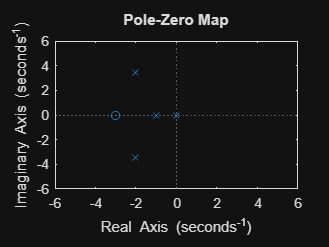

clear; clc;

%Análisis de LGR con funciones de transferencia
G = tf([1 3],[1 5 20 16 0]);
H = 1;

p = pole(G);
z = zero(G);

figure(1);
%Polos y ceros de lazo abierto
pzmap(G)
xlim([-6 6])
ylim([-6 6])

%Ángulos de las asíntotas
ta = 180/(length(pole(G))-length(zero(G)))

ta = 60

tb = 3*180/(length(pole(G))-length(zero(G)))

tb = 180

tc = 5*180/(length(pole(G))-length(zero(G)))

tc = 300

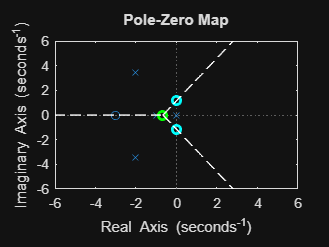


%Centroide
sigma_0 = (sum(pole(G))-sum(zero(G)))/(length(pole(G))-length(zero(G)));

%Gráficas de las asíntotas
xa = sigma_0:0.1:6;
xb = -6:0.1:sigma_0;
y1 = sqrt(3)*(xa - sigma_0);
y2 = -y1;
y3 = zeros(1,length(xb));

figure(2); hold on;

%Asíntotas
plot(xa, y1, 'white','LineStyle','--')
plot(xa, y2, 'white','LineStyle','--')
plot(xb, y3, 'white','LineStyle','--')
%Cortes de las asíntotas en el eje imaginario
plot(0,sqrt(3)*sigma_0,'o','LineWidth',2,'Color',"c")
plot(0,-sqrt(3)*sigma_0,'o','LineWidth',2,'Color',"c")
%Centroide
plot(sigma_0,0,'o','LineWidth',2,'Color',"g")
%Polos y ceros en lazo abierto
pzmap(G)
xlim([-6 6])
ylim([-6 6])
hold off;

%Ángulo de salida
t = 180 + 180/pi*(- angle(p(2)-p(1)) - angle(p(2)-p(3)) - angle(p(2)-p(4)) + angle(p(2)-z(1)))

t = -62.2042

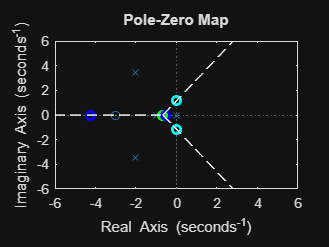


%Diferenciación para puntos de llegada
syms s;

num = s + 3;
den = s^4 + 5*s^3 + 20*s^2 + 16*s;

Gsym = num/den; 
dKsym = diff(-1/Gsym,s); %Derivada ecuación característica 

[num_dKsym, den_dKsym] = numden(dKsym); %Agrupación en numerador y denominador

%Coeficientes de polinomios
num_dK = sym2poly(num_dKsym);
den_dK = sym2poly(den_dKsym);

dK = tf(num_dK, den_dK); %Función de transferencia de la derivada de K(s)
arv = zero(dK); %Puntos de llegada

figure(3); hold on;

%Asíntotas
plot(xa, y1, 'white','LineStyle','--')
plot(xa, y2, 'white','LineStyle','--')
plot(xb, y3, 'white','LineStyle','--')
%Cortes de las asíntotas en el eje imaginario
plot(0,sqrt(3)*sigma_0,'o','LineWidth',2,'Color',"c")
plot(0,-sqrt(3)*sigma_0,'o','LineWidth',2,'Color',"c")
%Puntos de llegada (se llama solo a los que son puramente reales
plot(arv(1),0,'o', 'LineWidth',2,'Color',"b")
plot(arv(4),0,'o', 'LineWidth',2,'Color',"b")
%Centroide
plot(sigma_0,0,'o','LineWidth',2,'Color',"g")
%Polos y ceros en lazo abierto
pzmap(G)
xlim([-6 6])
ylim([-6 6])
hold off;

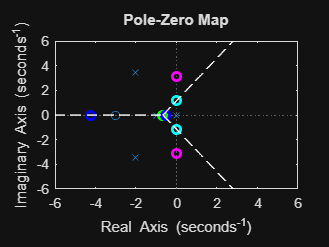

%Cortes con el eje imaginario
K_im = roots([1 7 -1344]); %Expresión K
im = roots([(84-K_im(2))/5 0 3*K_im(2)]); %Cortes

figure(4); hold on;

%Asíntotas
plot(xa, y1, 'white','LineStyle','--')
plot(xa, y2, 'white','LineStyle','--')
plot(xb, y3, 'white','LineStyle','--')
%Cortes de las asíntotas en el eje imaginario
plot(0,sqrt(3)*sigma_0,'o','LineWidth',2,'Color',"c")
plot(0,-sqrt(3)*sigma_0,'o','LineWidth',2,'Color',"c")
%Puntos de corte con el eje imaginario
plot(real(im(1)),imag(im(1)),'o', 'LineWidth',2,'Color',"m")
plot(real(im(2)),imag(im(2)),'o', 'LineWidth',2,'Color',"m")
%Puntos de llegada (se llama solo a los que son puramente reales
plot(arv(1),0,'o', 'LineWidth',2,'Color',"b")
plot(arv(4),0,'o', 'LineWidth',2,'Color',"b")
%Cortes de las asíntotas en el eje imaginario
plot(0,sqrt(3)*sigma_0,'o','LineWidth',2,'Color',"c")
plot(0,-sqrt(3)*sigma_0,'o','LineWidth',2,'Color',"c")
%Centroide
plot(sigma_0,0,'o','LineWidth',2,'Color',"g")
%Polos y ceros en lazo abierto
pzmap(G)
xlim([-6 6])
ylim([-6 6])
hold off;

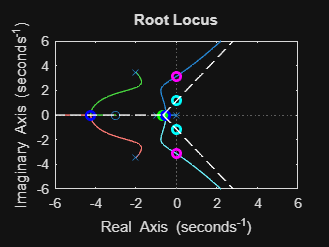

figure(5); hold on;

%Asíntotas
plot(xa, y1, 'white','LineStyle','--')
plot(xa, y2, 'white','LineStyle','--')
plot(xb, y3, 'white','LineStyle','--')
%Cortes de las asíntotas en el eje imaginario
plot(0,sqrt(3)*sigma_0,'o','LineWidth',2,'Color',"c")
plot(0,-sqrt(3)*sigma_0,'o','LineWidth',2,'Color',"c")
%Puntos de corte con el eje imaginario
plot(real(im(1)),imag(im(1)),'o', 'LineWidth',2,'Color',"m")
plot(real(im(2)),imag(im(2)),'o', 'LineWidth',2,'Color',"m")
%Puntos de llegada (se llama solo a los que son puramente reales
plot(arv(1),0,'o', 'LineWidth',2,'Color',"b")
plot(arv(4),0,'o', 'LineWidth',2,'Color',"b")
%Cortes de las asíntotas en el eje imaginario
plot(0,sqrt(3)*sigma_0,'o','LineWidth',2,'Color',"c")
plot(0,-sqrt(3)*sigma_0,'o','LineWidth',2,'Color',"c")
%Centroide
plot(sigma_0,0,'o','LineWidth',2,'Color',"g")
%Polos y ceros en lazo abierto
rlocus(G)
xlim([-6 6])
ylim([-6 6])
hold off;